# Zadanie 2 - Rezystywność

### Aleksander Cząstkiewicz - 260763

(poniżej kontrolka do zwiększania liczonych punktów - im więcej tym gęstsze wykresy)

dN=400;
N_d=logspace(14,20,dN);
N_d=N_d'; %[cm^-3]
% https://sci-hub.se/10.1109/t-ed.1983.21207
q=1.602e-19; %[C]
constants=[52.2 68.5 44.9;1417 1414 470.5;43.4 56.1 29.0;9.68e16 9.2e16 2.23e17;3.43e20 3.41e20 6.1e20;0.68 0.711 0.709;2 1.98 2];
mi=zeros(dN,3);
mi=constants(1,:)+(constants(2,:)-constants(1,:))./(1+(N_d./constants(4,:)).^constants(6,:))-constants(3,:)./(1+(constants(5,:)./N_d).^constants(7,:)); % [cm^2/s/V]
sigma=(mi.*N_d)*q; %[C/cm/s/V]=[1/cm/Omega]
rho=1./sigma; % rezystywnosc [Omega*cm]


    Korzystając z danych wyznaczonych eksperymentalni${\mathrm{e}}^{\left\lbrack 1\right\rbrack }$ i wzoru empiryczneg$o^{\left\lbrack 1\right\rbrack }$, obliczono ruchliwość głównych nośników dla domieszkowania Arsenem, Fosforem i Borem. Następnie używając powszechnie znanych wzorów wyliczono konduktywność i rezystancje dla tych domieszek. Wielkosci te zostały policzone dla różnych wartości domieszkowania i przedstawione na wykresach w zależności od domieszkowania. Wzór użyty to policzenia ruchliwości:

## 
$$\mu_n =\mu_0 +\frac{\mu_{\max } -\mu_0 }{1+{\left(\frac{N_d }{C_r }\right)}^{\alpha } }-\frac{\mu_1 }{1+{\left(\frac{C_s }{N_d }\right)}^{\beta } }\left\lbrack \frac{{\textrm{cm}}^2 }{s\cdot V}\right\rbrack$$


gdzie $N_d$ to koncentracja domieszkowania, a pozostałe wielkości to stałe opisane w tabeli:

rownames=["mu_0";"mu_{max}";"mu_1";"C_r";"C_s";"alpha";"beta"];
Arsen=constants(:,1);
Fosfor=constants(:,2);
Bor=constants(:,3);
table(Arsen,Fosfor,Bor,'RowNames',rownames)

ans = 7×3 table
                 Arsen       Fosfor       Bor   
                ________    ________    ________

    mu_0            52.2        68.5        44.9
    mu_{max}        1417        1414       470.5
    mu_1            43.4        56.1          29
    C_r         9.68e+16     9.2e+16    2.23e+17
    C_s         3.43e+20    3.41e+20     6.1e+20
    alpha           0.68       0.711       0.709
    beta               2        1.98           2


Obliczenia były robione z założeniem stałej temperatury 300K.

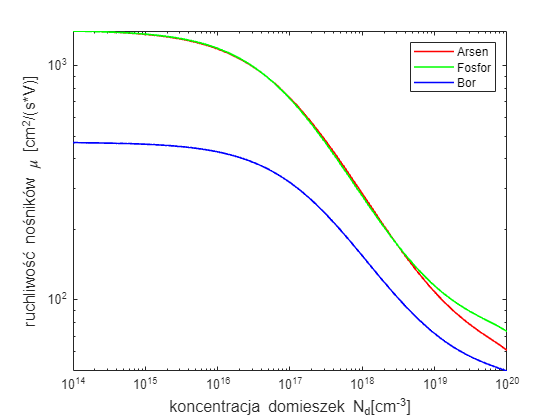


%subplot(1,3,1)
x=N_d;
y01=mi(:,1);
y02=mi(:,2);
y03=mi(:,3);
loglog(x,y01,'-r',x,y02,'-g',x,y03,'-b','LineWidth',1.25);
xlabel("koncentracja domieszek N_d[cm^{-3}]","FontSize",12);
ylabel("ruchliwość nośników \mu [cm^2/(s*V)]","FontSize",12);
legend("Arsen","Fosfor","Bor","Location","northeast");

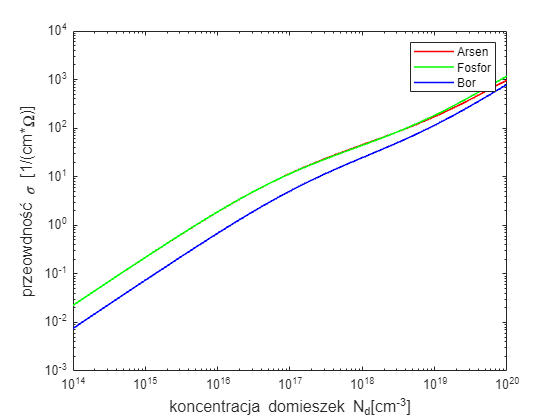


y11=sigma(:,1);
y12=sigma(:,2);
y13=sigma(:,3);
loglog(x,y11,'-r',x,y12,'-g',x,y13,'-b','LineWidth',1.25);
xlabel("koncentracja domieszek N_d[cm^{-3}]","FontSize",12);
ylabel("przeowdność \sigma [1/(cm*\Omega)]","FontSize",12);
legend("Arsen","Fosfor","Bor","Location","northeast");

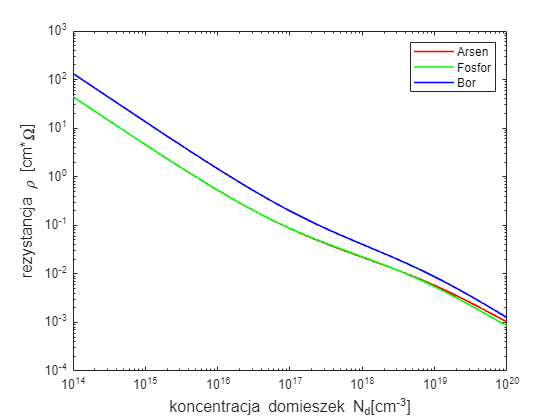


y21=rho(:,1);
y22=rho(:,2);
y23=rho(:,3);
loglog(x,y21,'-r',x,y22,'-g',x,y23,'-b','LineWidth',1.25);
xlabel("koncentracja domieszek N_d[cm^{-3}]","FontSize",12);
ylabel("rezystancja \rho [cm*\Omega]","FontSize",12);
legend("Arsen","Fosfor","Bor","Location","northeast");

    Różnica ilościowa dla wyników dla domieszkowania Borem wynika najprawdopodbniej z faktu iż Bor jest z grupy III, a więc jest głównie donorem dziur. W przeciwieństwie do Arsenu i Fosforu, które należą do grupy V i głównie donorują elektrony.

## Źródła:

[1] G. Masetti, G., Severi, M., & Solmi, S. (1983). Modeling of carrier mobility against carrier concentration in arsenic-, phosphorus-, and boron-doped silicon. IEEE Transactions on Electron Devices, ( Volume: 30, Issue: 7, July 1983),Page(s): 764–769. DOI:10.1109/t-ed.1983.21207

[2] Instytut Fizyko Techniczny imienia A. F. Ioffego Rosyjskiej Akademii Nauk w Petersburgu

http://www.ioffe.ru/SVA/NSM/Semicond/Si